# ECG Signal Processing and Heart Rate Analysis using MATLAB

Inspection

clc; clear all; close all;

data = readmatrix('Data Analytics/100.csv');

size(data)

ans =       650000           3


data(1:10,:)

ans =            0         995        1011
           1         995        1011
           2         995        1011
           3         995        1011
           4         995        1011
           5         995        1011
           6         995        1011
           7         995        1011
           8        1000        1008
           9         997        1008


data = data(~any(isnan(data),2), :);
ecg = data(:,2);   % primary lead


ecg = repelem(ecg,3);   % stronger stretch
fs = 360 / 3;

Plot External ECG

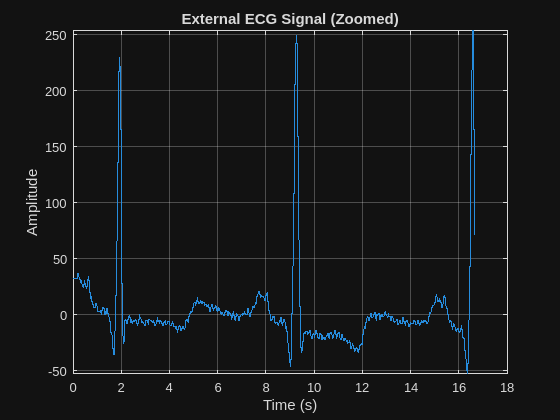


ecg = ecg - mean(ecg);

t = (0:length(ecg)-1)/fs;

N = 2000;

figure;
plot(t(1:N), ecg(1:N));
title('External ECG Signal (Zoomed)');
xlabel('Time (s)');
ylabel('Amplitude');
ylim([min(ecg(1:N)), max(ecg(1:N))])
grid on;

Filtering

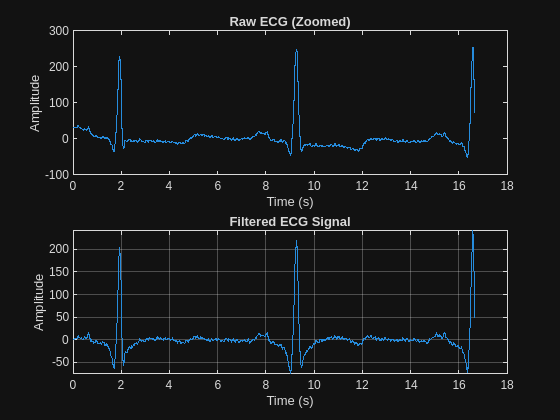

[b1, a1] = butter(2, 0.5/(fs/2), 'high');
ecg_hp = filtfilt(b1, a1, ecg);

[b2, a2] = butter(4, 40/(fs/2), 'low');
ecg_filtered = filtfilt(b2, a2, ecg_hp);

figure;

subplot(2,1,1);
plot(t(1:N), ecg(1:N));
title('Raw ECG (Zoomed)');
xlabel('Time (s)');
ylabel('Amplitude');

subplot(2,1,2);
plot(t(1:N), ecg_filtered(1:N));
title('Filtered ECG Signal');
xlabel('Time (s)');
ylabel('Amplitude');

ylim([min(ecg_filtered(1:N)) max(ecg_filtered(1:N))]);
grid on;

R-peak detection

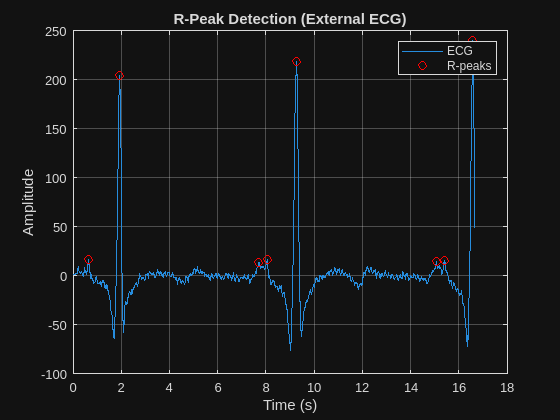

segment = ecg_filtered(1:N);

threshold = mean(segment) + 0.3 * std(segment);

min_distance = round(0.3 * fs);

[peaks, locs] = findpeaks(segment, ...
    'MinPeakHeight', threshold, ...
    'MinPeakDistance', min_distance);

figure;
plot(t(1:N), segment); hold on;

plot(t(locs), peaks, 'ro');

title('R-Peak Detection (External ECG)');
xlabel('Time (s)');
ylabel('Amplitude');
legend('ECG', 'R-peaks');
grid on;

BPM Calculation

RR_intervals = diff(locs) / fs;
BPM = 60 ./ RR_intervals;
avg_BPM = median(BPM);

fprintf('Average Heart Rate: %.2f BPM\n', avg_BPM);

Average Heart Rate: 50.00 BPM


fprintf('Detected Peaks: %d\n', length(locs));

Detected Peaks: 8


fprintf('Min BPM: %.2f\n', min(BPM));

Min BPM: 10.30


fprintf('Max BPM: %.2f\n', max(BPM));

Max BPM: 184.62


Classification

if avg_BPM < 60
    condition = 'Bradycardia';
elseif avg_BPM > 100
    condition = 'Tachycardia';
else
    condition = 'Normal';
end

fprintf('Condition: %s\n', condition);

Condition: Bradycardia
